# Thermoeconomic Analysis of a Polygeneration plant

In this file we analize a polygeneration plant, which produce electricity (`WN=WICE+WGT)`, Steam (`QV), `and Hot Water (`QHW)`.The plant also produce waste gases` QG.`

The plant use three different types of Fuel Resources: Natural Gas` (NG)`, Biodiesel` (BD)` and Propane Gas `(PG)`.

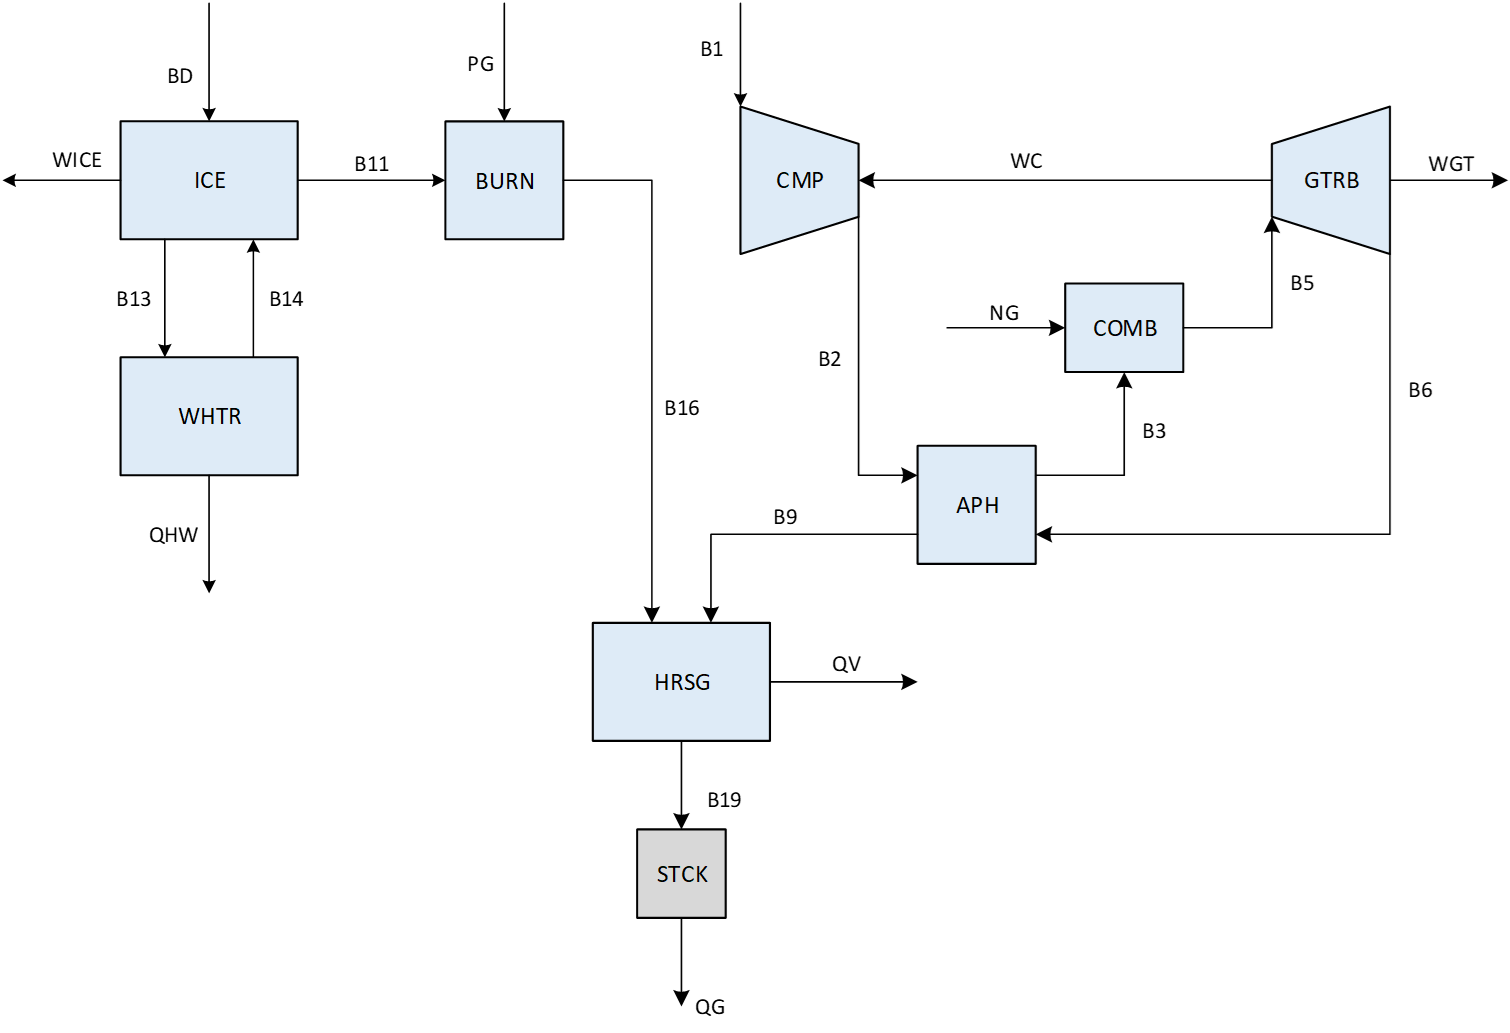

### Read the data model

Read Data Model and show the data model tables 

filename='polygen_model.json';
data=ReadDataModel(filename,'Show',true);


Flows Data

 key    type      
————————————————————
 B2     INTERNAL  
 B3     INTERNAL  
 NG     RESOURCE  
 B5     INTERNAL  
 B6     INTERNAL  
 WC     INTERNAL  
 WGT    INTERNAL  
 B9     INTERNAL  
 BD     RESOURCE  
 B11    INTERNAL  
 WICE   INTERNAL  
 B13    INTERNAL  
 B14    INTERNAL  
 PG     RESOURCE  
 B16    INTERNAL  
 QHW    OUTPUT    
 QV     OUTPUT    
 B19    INTERNAL  
 WN     OUTPUT    
 QG     WASTE     


Processes Data

 key    type          fuel         product   
———————————————————————————————————————————————
 CMB    PRODUCTIVE    NG+B3        B5        
 APH    PRODUCTIVE    B6-B9        B3-B2     
 CMP    PRODUCTIVE    WC           B2        
 GTRB   PRODUCTIVE    B5-B6        WGT+WC    
 ICE    PRODUCTIVE    BD+B14-B13   WICE+B11  
 WHTR   PRODUCTIVE    B13-B14      QHW       
 BURN   PRODUCTIVE    PG           B16-B11   
 HRSG   PRODUCTIVE    B16+B9-B19   QV        
 GEN    PRODUCTIVE    WICE+WGT     WN        
 STCK   DISSIPATIVE   B19          QG    

### Thermoeconomic Analysis

Load the thermoeconomic Model, activating the Generalized cost tables and Summary Resources. Print Available results when using conventional diesel in the ICE.

model = ThermoeconomicModel(data,'CostTables','GENERALIZED','Summary','RESOURCES','Debug',false);
showProperties(model);

 
              State: 'Reference'
     ReferenceState: 'Reference'
     ResourceSample: 'Diesel'
         CostTables: 'GENERALIZED'
    DiagnosisMethod: 'WASTE_EXTERNAL'
        ActiveWaste: 'QG'
            Summary: 'RESOURCES'
          Recycling: 'false'
              Debug: 'false'
     IsResourceCost: 'true'
        IsDiagnosis: 'false'
          IsSummary: 'true'
            IsWaste: 'true'



printResults(model);


Flows Definition Table - Reference

  Id Key   From     To       Type      
————————————————————————————————————————
   1 B2    CMP_P1   APH_P1   INTERNAL  
   2 B3    APH_P1   CMB_F1   INTERNAL  
   3 NG    ENV_R1   CMB_F1   RESOURCE  
   4 B5    CMB_P1   GTRB_F1  INTERNAL  
   5 B6    GTRB_F1  APH_F1   INTERNAL  
   6 WC    GTRB_P1  CMP_F1   INTERNAL  
   7 WGT   GTRB_P1  GEN_F1   INTERNAL  
   8 B9    APH_F1   HRSG_F1  INTERNAL  
   9 BD    ENV_R2   ICE_F1   RESOURCE  
  10 B11   ICE_P1   BURN_P1  INTERNAL  
  11 WICE  ICE_P1   GEN_F1   INTERNAL  
  12 B13   ICE_F1   WHTR_F1  INTERNAL  
  13 B14   WHTR_F1  ICE_F1   INTERNAL  
  14 PG    ENV_R3   BURN_F1  RESOURCE  
  15 B16   BURN_P1  HRSG_F1  INTERNAL  
  16 QHW   WHTR_P1  ENV_O1   OUTPUT    
  17 QV    HRSG_P1  ENV_O2   OUTPUT    
  18 B19   HRSG_F1  STCK_F1  INTERNAL  
  19 WN    GEN_P1   ENV_O3   OUTPUT    
  20 QG    STCK_P1  ENV_W1   WASTE     


Productive Groups Definition Table - Reference

  Id Key      Definition  Type  

#### Plot the generalized unit cost summary for system output flows

This graph compare the non-renewable cost of the system final products when use conventional diesel fuel or biodiesel in the ICE

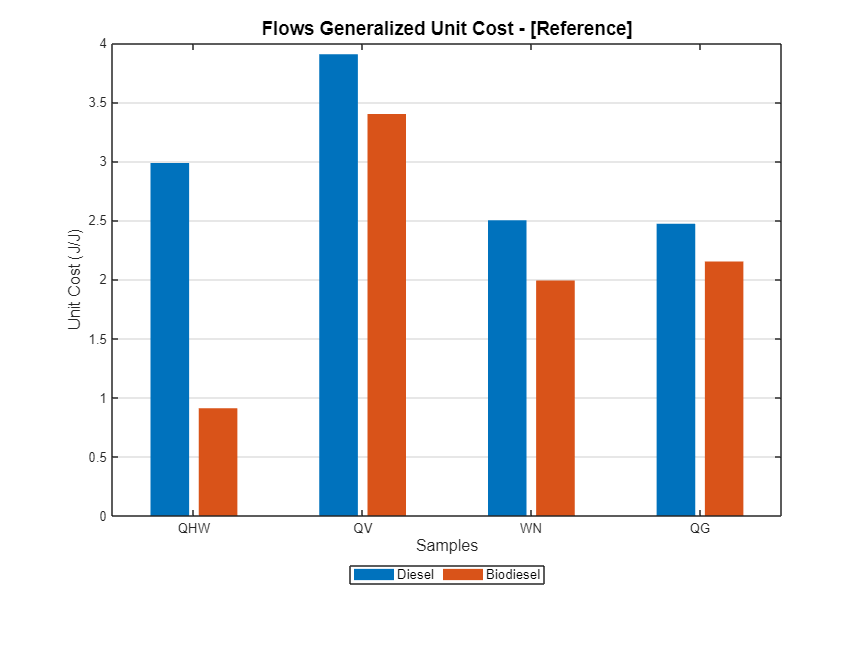

ShowGraph(model,'Graph','rgfuc');

### Generalized non-renewable results when using Biodiesel

Print the tables when use biodiesel resources

model.CurrentSample='Biodiesel';
model.showProperties;

 
              State: 'Reference'
     ReferenceState: 'Reference'
     ResourceSample: 'Biodiesel'
         CostTables: 'GENERALIZED'
    DiagnosisMethod: 'WASTE_EXTERNAL'
        ActiveWaste: 'QG'
            Summary: 'RESOURCES'
          Recycling: 'false'
              Debug: 'false'
     IsResourceCost: 'true'
        IsDiagnosis: 'false'
          IsSummary: 'true'
            IsWaste: 'true'



printResults(model);


Flows Definition Table - Reference

  Id Key   From     To       Type      
————————————————————————————————————————
   1 B2    CMP_P1   APH_P1   INTERNAL  
   2 B3    APH_P1   CMB_F1   INTERNAL  
   3 NG    ENV_R1   CMB_F1   RESOURCE  
   4 B5    CMB_P1   GTRB_F1  INTERNAL  
   5 B6    GTRB_F1  APH_F1   INTERNAL  
   6 WC    GTRB_P1  CMP_F1   INTERNAL  
   7 WGT   GTRB_P1  GEN_F1   INTERNAL  
   8 B9    APH_F1   HRSG_F1  INTERNAL  
   9 BD    ENV_R2   ICE_F1   RESOURCE  
  10 B11   ICE_P1   BURN_P1  INTERNAL  
  11 WICE  ICE_P1   GEN_F1   INTERNAL  
  12 B13   ICE_F1   WHTR_F1  INTERNAL  
  13 B14   WHTR_F1  ICE_F1   INTERNAL  
  14 PG    ENV_R3   BURN_F1  RESOURCE  
  15 B16   BURN_P1  HRSG_F1  INTERNAL  
  16 QHW   WHTR_P1  ENV_O1   OUTPUT    
  17 QV    HRSG_P1  ENV_O2   OUTPUT    
  18 B19   HRSG_F1  STCK_F1  INTERNAL  
  19 WN    GEN_P1   ENV_O3   OUTPUT    
  20 QG    STCK_P1  ENV_W1   WASTE     


Productive Groups Definition Table - Reference

  Id Key      Definition  Type  

#### Plot Process Irreversibility-Cost Table

Show the graph for the irreversibility-cost table

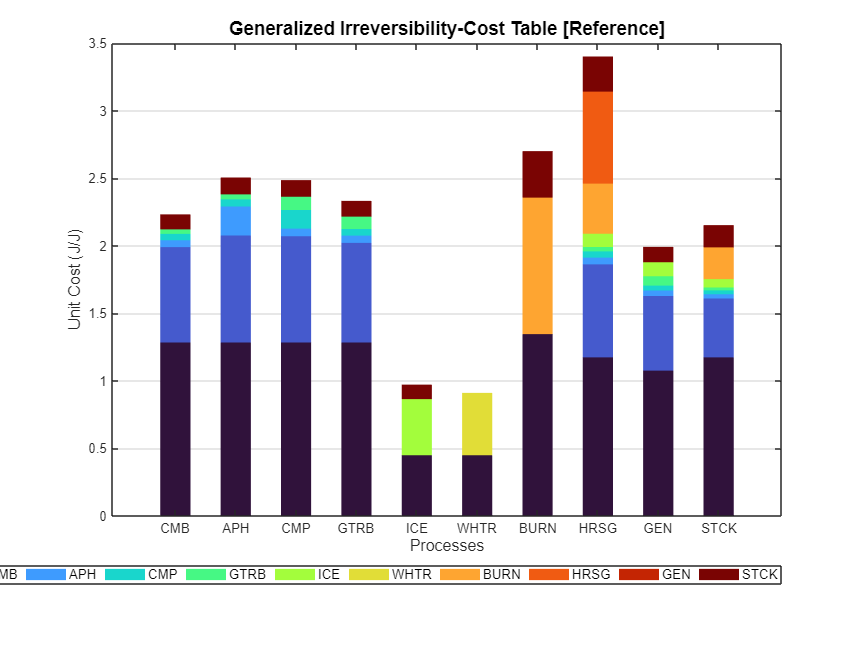

ShowGraph(model,'Graph','gict');

### Show the Resource Cost decomposition graph

The default graph shows a bar graph with the resources cost decomposition

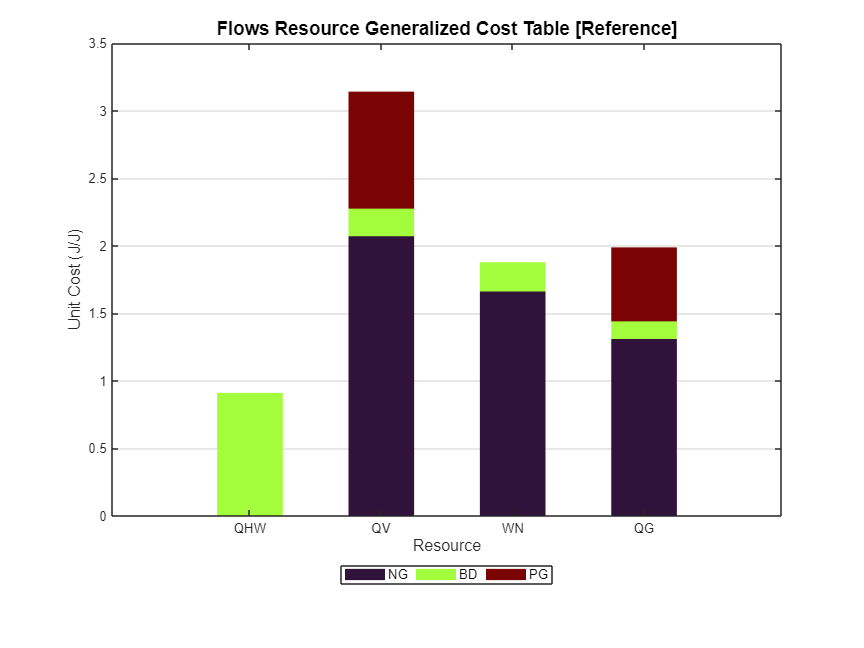

ShowGraph(model,'Graph','gfrsc');

The pie chart show the % contibution of each resource to the production of steam

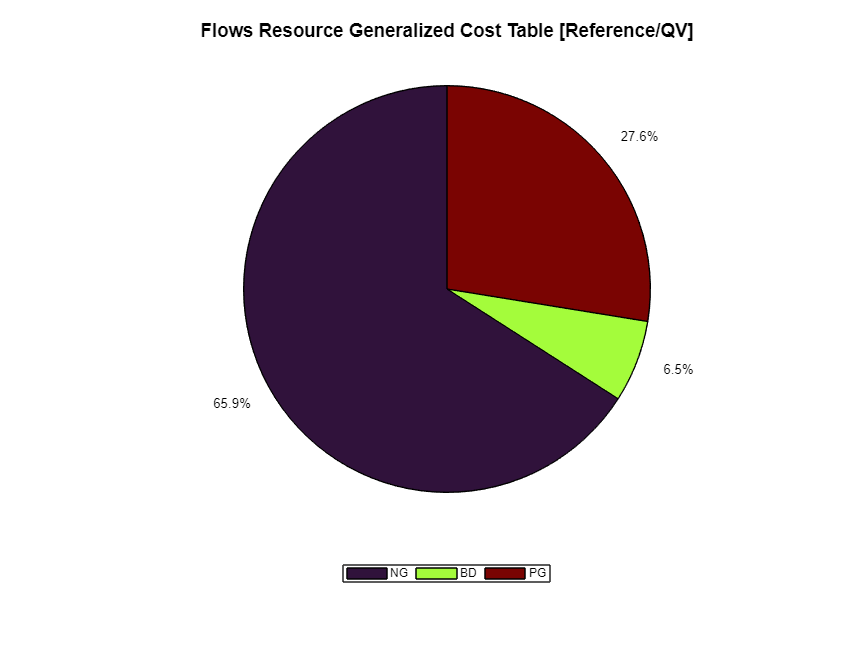

ShowGraph(model,'Graph','gfrsc','Variables','QV');